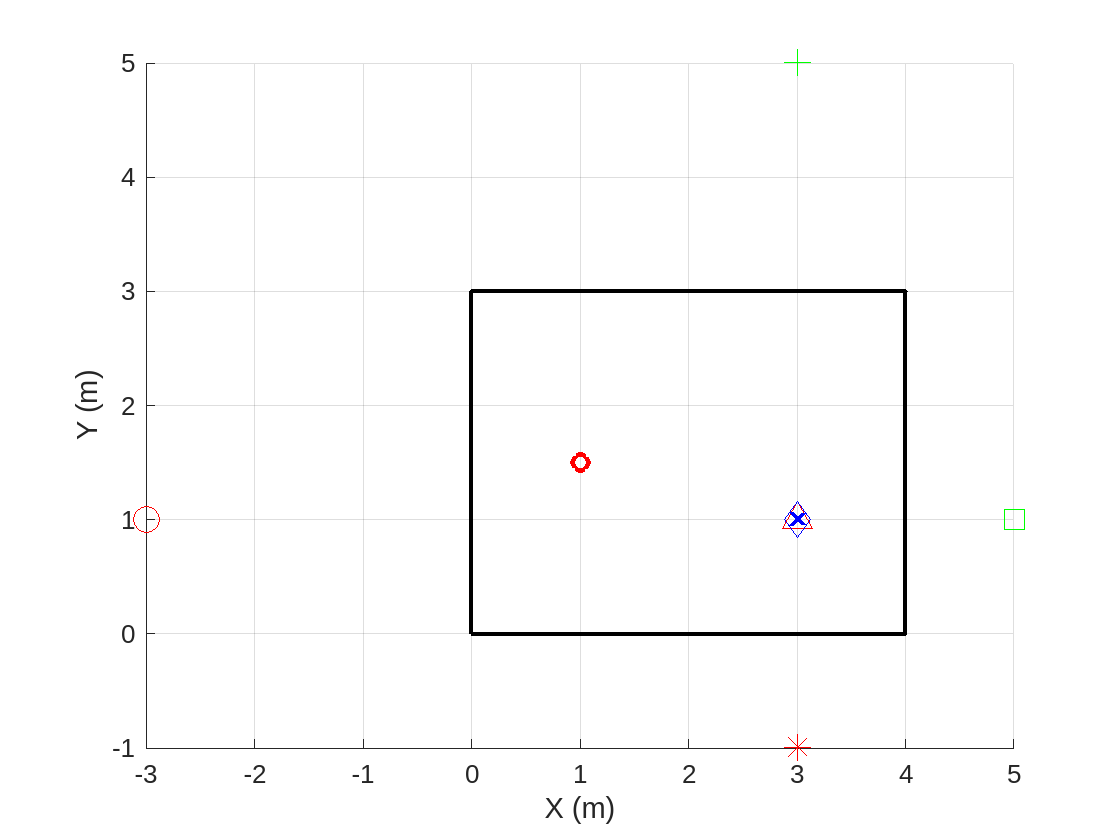

%Main+
%Boolean Flag, make false for turning of Ray-tracing.
bFlag = false;
h2 = figure;
roomDimensions = [4 3 3];
receiverCoord = [1 1.5 1];
sourceCoord = [3 1 2];

%Pre-defined plane names for view type 3.
planeNameTags = ["Left face","Right face", "Top face","Bottom face", "Back face","Front face" ];

plotStyles = {'ro', 'gs', 'bd', 'r^', 'g+', 'r*', 'k.', 'rx'};
%Plot room for given params.
plotRoom(roomDimensions,receiverCoord,sourceCoord,h2);

%Generate Cube planes
cubePlanes = generateCubePlanes(roomDimensions(1),roomDimensions(2) , roomDimensions(3));

%Generate 1st Order image sources
result=plot1stOrdImgSrc(roomDimensions,sourceCoord);

hold on

for index=1:6
    isourceCoord=result(index,:);
    %Plot each image soruce and the corresponding Ray-traces in red.

    plot3(isourceCoord(1),isourceCoord(2),isourceCoord(3),plotStyles{index}, "MarkerSize",10);

    %Extrcting the cube plane vertices of the corresponding name tag.
    rowData = refPlanePointExtrct(cubePlanes, planeNameTags(index));
    %Compute each intersection point by evaluating each plane and recvier
    %cordinates.
    intersection_point = interSecFind(receiverCoord, result(index,:), rowData);
    if(bFlag)
        px =[sourceCoord(1),intersection_point(1),receiverCoord(1)];
        py=[sourceCoord(2),intersection_point(2),receiverCoord(2) ];
        pz =[sourceCoord(3),intersection_point(3), receiverCoord(3)];
        plot3(px,py,pz, "LineWidth", 2);
        px =[isourceCoord(1),intersection_point(1)];
        py=[isourceCoord(2),intersection_point(2)];
        pz =[isourceCoord(3),intersection_point(3)];
        plot3(px,py,pz, "LineWidth", 2, LineStyle="--");


    end
end


hold off